close all
clear variables

## Data

pressureLow1 = importdata ("231_PL1.csv")    ;
pressureLow2 = importdata ("231_PL2.csv")    ;
pressureLow3 = importdata ("231_PL3.csv")    ;
pressureHi1  = importdata ("231_PH1.csv")    ; 
pressureHi2  = importdata ("231_PH2.csv")    ;

timeLow1 = importdata ("231_TL1.csv")        ;
timeLow2 = importdata ("231_TL2.csv")        ;
timeLow3 = importdata ("231_TL3.csv")        ;

timeHi1 = importdata ("231_TH1.csv")         ;
timeHi2 = importdata ("231_TH2.csv")         ;

## Calcs

pressureHi1 = log (pressureHi1 - 0.7);
pressureHi2 = log (pressureHi2 - 0.72);

## Plots

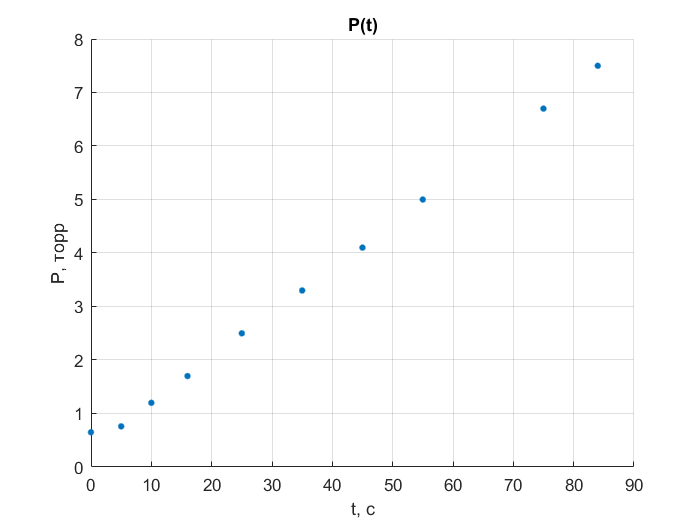

fg1 = figure;

xlabel ("t, c")
legend ("hide")
grid on

hold on

    ylabel ("P, торр")
    title  ('P(t)')
    plot (timeLow1, pressureLow1, '.', "MarkerSize", 12)
    saveas(fg1, "231_PL1.png")                                                   
    
hold off

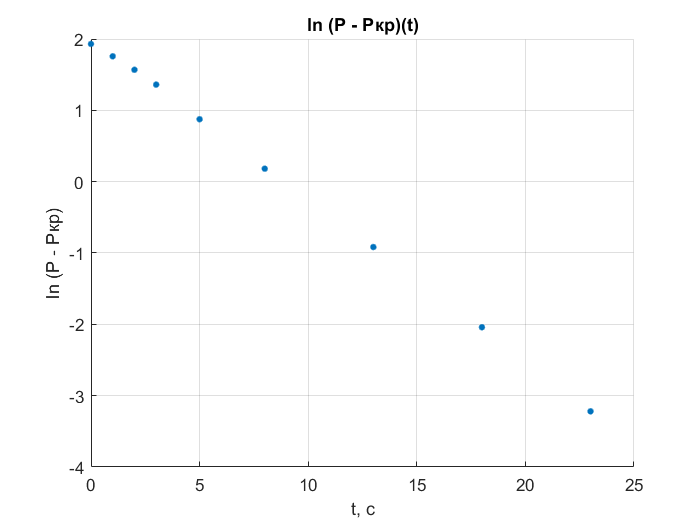


cla

hold on

    ylabel ("ln (P - Pкр)")
    title  ('ln (P - Pкр)(t)')
    plot (timeHi1, pressureHi1, '.', "MarkerSize", 12)
    saveas(fg1, "231_PH1.png")                                                   
    
hold off

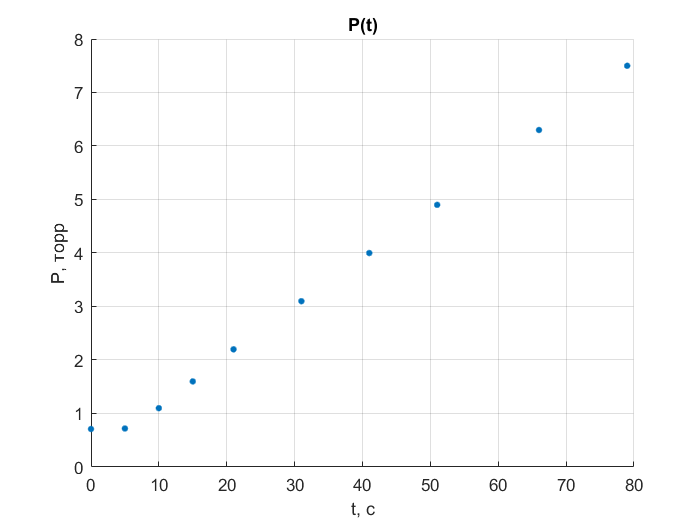


cla

hold on

    ylabel ("P, торр")
    title  ('P(t)')
    plot (timeLow2, pressureLow2, '.', "MarkerSize", 12)
    saveas(fg1, "231_PL2.png")                                                   
    
hold off

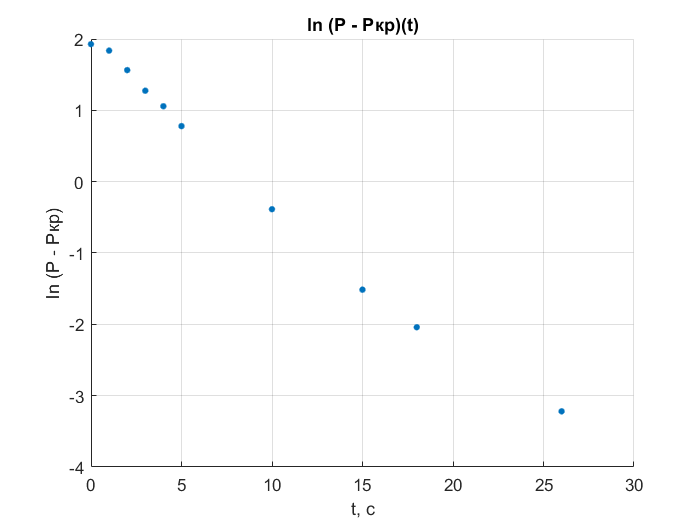



cla

hold on

    ylabel ("ln (P - Pкр)")
    title  ('ln (P - Pкр)(t)')
    plot (timeHi2, pressureHi2, '.', "MarkerSize", 12)
    saveas(fg1, "231_PH2.png")                                                   
    
hold off

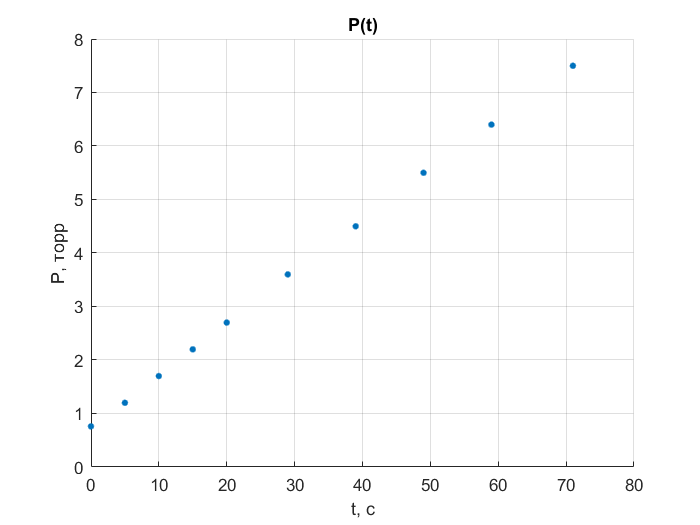



cla

hold on

    ylabel ("P, торр")
    title  ('P(t)')
    plot (timeLow3, pressureLow3, '.', "MarkerSize", 12)
    saveas(fg1, "231_PL3.png")                                                   
    
hold off